%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

Qs = [1e4 1e5 1e6 1e7];


Q_resonator_original = 100000

for j = 1 : length(Qs)
    f_0 = f_a;

band_width = 4.8355e+03

    Q_resonator_original = Qs(j)
    Q_resonator = Q_resonator_original / heterodyning_ratio;
    band_width = f_0 / Q_resonator
    band = [f_0-band_width/2, f_0+band_width/2];
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_resonator_original);
    
    R = @(f_ax, f_res) 1 ./ (1 + 4*Q_resonator_original^2 * (f_ax - f_res).^2 ./ f_res.^2 );
    
    signal_resonated = zeros(size(t));

f_current = 2.4177e+07

start_small = 125

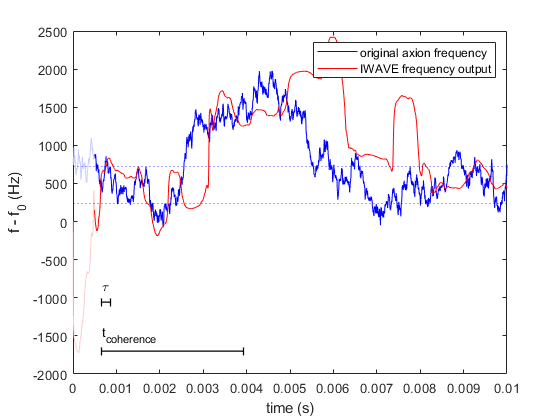

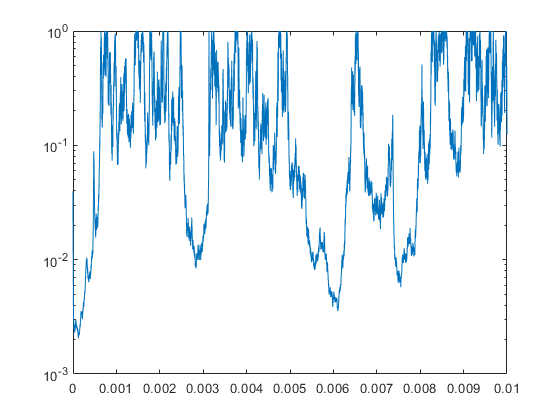

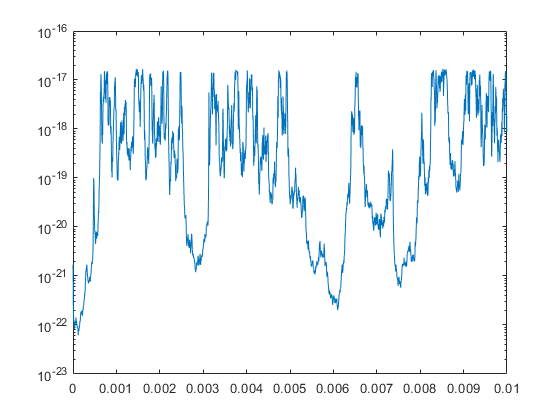

ans = 632.1409

ans = 915.8061

    noise_resonated = zeros(size(t));

    state_res = resonator_setup();
    for i = 1 : length(t)
        x = signal(i);
        x = x * R(f_axion(i), f_0);
        [state_res, y] = resonator_step(state_res, x, f_current, Q_resonator, f_sampling);
        signal_resonated(i) = y;
    end

    state_res = resonator_setup();
    for i = 1 : length(t)
        x = noise(i);
        x = x * R(f_axion(i), f_0);
        [state_res, y] = resonator_step(state_res, x, f_current, Q_resonator, f_sampling);
        noise_resonated(i) = y;
    end


    SNR = bandpower(signal, f_sampling, band) / bandpower(noise, f_sampling, band)
end